# Investigate Misclassifications

Instructions are in the task pane to the left. Complete and submit each task one at a time. Do not edit. This code loads the data and a trained kNN model and makes a confusion chart.

load letterdata.mat
load predmodel.mat
testdata

testdata = 968×26 table
    AspectRatio     MADX       MADY        AvgU        MADU        AvgV       MADV      CorrXY      CorrXP       CorrXU       CorrXV       CorrYP       CorrYU        CorrYV       CorrPU      CorrPV       CorrUV     NumXMin    NumXMax    NumYMin    NumYMax    NumUMin    NumUMax    NumVMin    NumVMax    Character
    ___________    _______    _______    _________    _______    ________    ______    _______

predLetter

predLetter = 968×1 categorical array
     E 
     F 
     G 
     J 
     M 
     P 
     T 
     Z 
     D 
     M 
     G 
     R 
     S 
     T 
     K 
     B 
     C 
     D 
     T 
     I 
     K 
     O 
     R 
     S 
     V 
     V 
     Z 
     E 
     G 
     J 


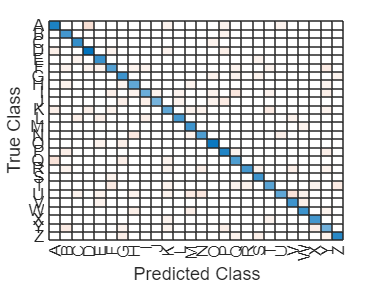

confusionchart(testdata.Character,predLetter);

## Task 1

When making a confusion chart, you can add information about the false negative and false positive rate for each class by adding row or column summaries, respectively.

`confusionchart``(``...,``"RowSummary"``,``"row-normalized"``)``;`

**TASK**

Recreate the confusion chart with normalized row summary information.

**Hint**

Copy the `confusionchart` command from the beginning of the script. Add the `"RowSummary"` option with the value `"row-normalized"`.

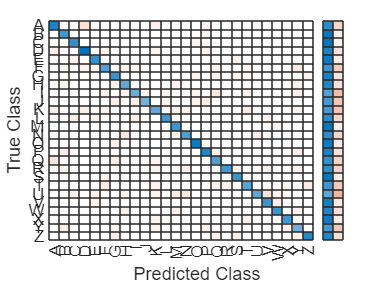

confusionchart(testdata.Character,predLetter,"RowSummary","row-normalized");

## Task 2

You can use relational and logical operators (such as `==`, `~=`, `&`, and `|`) to identify observations to study further.

**TASK**

Use relational and logical operators to create a logical array called `falseneg` that identifies instances of the test data where the letter U was classified as something else. That is, elements where the true class (`testdata.Character`) is "U" and the predicted class (`predLetter`) was not "U".

**Hint**

Use the `==` operator to compare `testdata.Character` to the class `"U"` and the `~=` operator to compare `predLetter` to `"U"`. Use the `&` operator to combine these conditions.

falseneg = (testdata.Character == "U") & (predLetter ~= "U");

## Task 3

Recall that the `Files` property of a datastore contains the file names of the original data. Hence, when you import the data and extract the features, you can keep a record of which data file is associated with each observation. The string array `testfiles` contains the file names for the test data.

**TASK**

Use the logical array `falseneg` as an index into `testfiles` to determine the file names of the observations that were incorrectly classified as the letter U. Store the result in a variable called `fnfiles`.

Similarly, use `falseneg` as an index into `predLetter` to determine the associated predicted letters. Store the result in a variable called `fnpred`.

**Hint**

Evaluate `testfiles``(``falseneg``)` and `predLetter``(``falseneg``)`. Assign the results to the given variable names.

fnfiles = testfiles(falseneg)

Unrecognized function or variable 'testfiles'.

fnpred = predLetter(falseneg)

## Task 4

The fourth element of `fnpred` is N, which is a common misclassification for the letter U. What does this particular sample look like?

**TASK**

Use the `readtable` function to import the data in the fourth element of `fnfiles` into a table called `badU`. Visualize the letter by plotting `Y` against `X`.

**Hint**

Pass `fnfiles``(``4``)` as an input to the `readtable` function. Assign the result to `badU`. Then pass `badU.X` and `badU.Y` as inputs to the `plot` function.

badU = readtable(fnfiles(4));
plot(badU.X,badU.Y)

## Further Practice

Think about the pen position through time for this U and for a typical N. Is it reasonable that they could be confused with each other?

Try looking at some of the other misclassifications. You can add a title to the plot to show what the model predicted:

`title``(``"Prediction: "``+``string``(``fnpred``(``4``)))`

title("Prediction: "+string(fnpred(4)))